## Problem 3

A column is made of a certain material with Young modulus $E = 181\times 10^{6}\, \text{kN/m}^{2}$ The geometry of the column is shown in the figure. We wish to analyze the column for displacements using the FEM.

                                     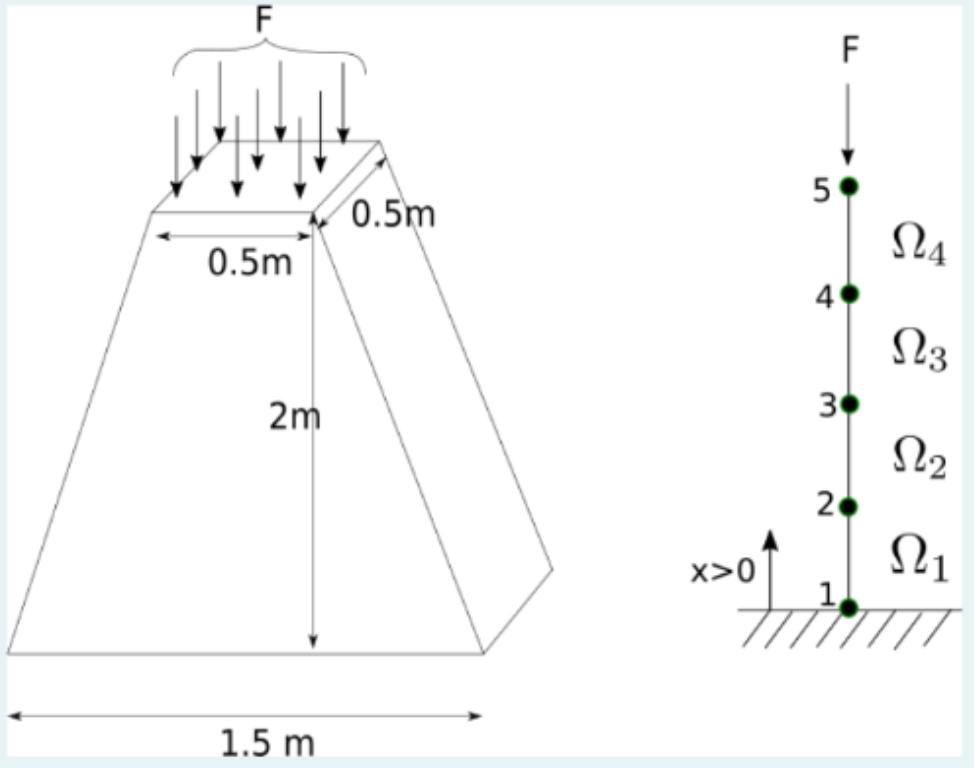

The column is indeed a three-dimensional structure. However, we wish to approximate the column as one dimensional. To this end, we represent the distributed force at the top of the column as a point force $F = 5\, \text{kN}$.

    The weight of the material is represented by the body force per unit lenght: $f(x) = -6.25 (3 - x)\ \text{kN/m}$. The governing differential equation for the problem is given by $-\frac{\mathrm{d}}{\mathrm{d} x}\left(E A(x) \frac{\mathrm{d} u}{\mathrm{d} x}\right) = f(x)$ where $A(x)$ is the cross-sectional area.

    Consider a mesh with $4$ linear elements of equal length $h = 0.5\; \text{m}$.

### Solution

We give the formulae needed to solve the exercise, before solving the quaetions.

#### Formulae

Shape functions of  the linear 1D element $\Omega^{e}$:

                                            
$$\psi^{e}_{1}(x) = \frac{x-x^{e}_{2}}{x^{e}_{1} - x^{e}_{2}},\qquad\qquad
\psi^{e}_{2}(x) = \frac{x-x^{e}_{1}}{x^{e}_{2} - x^{e}_{1}}.\qquad\qquad
$$


Components of the local stiffness matrix.

                                          
$$K^{e}_{i,j} = \int_{x^{e}_{1}}^{x^{e}_{2}} a_{1}(x) \frac{\mathrm{d}\psi^{e}_{i}}{\mathrm{d} x}(x) \frac{\mathrm{d}\psi^{e}_{j}}{\mathrm{d} x}(x)\; \mathrm{d} x,$$


$i, j = 1, 2$. In this case in point, $a_{1}(x) = E A(x)$, and we've seen in class, that for this truncated-wedge shped column, the sectional area changes linearly with the height $x$, so we can write $A(x) = \alpha x + \beta$. As, for $x = 0$, $A(0) = \frac{3}{2}\times \frac{1}{2} = \frac{3}{4}$ and, for $x = 2$, $A(2) = \frac{1}{2}\times\frac{1}{2} = \frac{1}{4}$. Therefore,

                                        
$$\begin{array}{lcr}
0 \alpha + \beta &\!\!\!\!\!\!\! = \!\!\!\! & \frac{3}{4},\\
2 \alpha + \beta &\!\!\!\!\!\!\! = \!\!\!\! &\frac{1}{4},
\end{array}
$$


 and, solving the system we get $\alpha = - \frac{1}{4}$, $\beta = \frac{3}{4}$. So,

                                       $A(x) = \frac{3}{4} - \frac{\alpha}{4}$.

Hence, the components of matrix $K^{e}$ are,

                                        
$$\begin{array}{rcl}
K^{e}_{1,1} &\!\!\!\!\!\!\!=\!\!\!\!
& \int_{x^{e}_{1}}^{x^{e}_{2}} E A(x) 
\frac{\mathrm{d}\psi^{e}_{1}}
{\mathrm{d}x}(x) \frac{\mathrm{d}\psi^{e}_{1}}
{\mathrm{d}x}(x)\mathrm{d} x \\
&\!\!\!\!\!\!\!=\!\!\!\!&
\frac{E}{\left(x^{e}_{2}-x^{e}_{1}\right)^{2}}\int_{x^{e}_{1}}^{x^{e}_{2}}
\left(\alpha x + \beta\right)\mathrm{d} x =
\frac{E}{h^{e}}\left(\alpha\frac{x^{e}_{1} + x^{e}_{2}}{2} + \beta\right)
= K^{e}_{2,2},\\
K^{e}_{1,2} &\!\!\!\!\!\!\!=\!\!\!\!& K^{e}_{2,1} = - K^{e}_{1,1},
\end{array}$$


being $x^{e}_{1}$ and $x^{e}_{2}$ the positions of the first and second node, respectively, of the element $\Omega^{e}$, so    $h^{e} = x^{e}_{2} - x^{e}_{1}$ is its corresponding length, for $e = 1,2,3,4$.

Next, to compute the components of the body force vector, we know that these are given by the quadratures,

                                        
$$F^{e}_{i} = \int_{x^{e}_{1}}^{x^{e}_{2}} f(x) \psi^{e}_{i}(x)\mathrm{d} x,
$$


$i=1,2$. In this exercise $f(x)$ is an affine function, i.e., a function of type $f(x) = \gamma x + \delta$, with coefficients: 

                                        
$$\gamma = 6.25,\quad \delta = -6.25\times 3 = -18.75.$$


After computing the integrals we get,

                                       
$$\begin{array}{l}
    F^{e}_{1} =
        \displaystyle\int_{x^{e}_{1}}^{x^{e}_{2}}
        \left(\gamma x + \delta\right)
        \frac{x-x^{e}_{2}}
        {x^{e}_{1}-x^{e}_{2}}\mathrm{d} x =
        h^{e}\left(
        \gamma\frac{2x^{e}_{1} + x^{e}_{2}}{6}
        + \frac{\delta}{2}\right),\\[15pt]
    F^{e}_{2} =
        \displaystyle\int_{x^{e}_{1}}^{x^{e}_{2}}
        \left(\gamma x + \delta\right)
        \frac{x-x^{e}_{1}}
        {x^{e}_{2}-x^{e}_{1}}\mathrm{d} x =
        h^{e}\left(
        \gamma\frac{x^{e}_{1} + 2 x^{e}_{2}}{6}
        + \frac{\delta}{2}\right),
\end{array}
$$


being $h^{e} = x^{e}_{2} - x^{e}_{1}$, the length of the element $\Omega^{e}$, for$e = 1,2,3,4$. 

#### Questions          

(a) *(3 points)* The value $K_{2,3}$ of the stiffness matrix is:

- Empty answer (no penalty)

- $\texttt{-2.0362e+08}\; \text{kN/m}$ 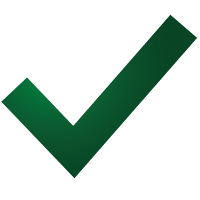

- 
$$\texttt{-1.8326e+08}\; \text{kN/m}$$


- 
$$\texttt{-2.2806e+08}\; \text{kN/m}$$


- 
$$\texttt{-2.2602e+08}\; \text{kN/m}$$


**Solution of part (a)**:

*Global Stifness Matrix. *The positions of the nodes are

    
$$x^{1}_{1} = x_{1} = 0,\quad x^{1}_{2} = x^{2}_{1} = x_{2} = 1/2,\quad x^{2}_{2} = x^{3}_{1} = x_{3} = 1,\quad x^{3}_{2} = x^{4}_{1} = x_{4} = 3/2,\quad x^{4}_{2} = x_{5} = 2.$$


 so, the the length of the  elements are $h^{e} = x^{e}_{2}  - x^{e}_{1} = 1/2$, for each element $e = 1,2,3,4$. Thus, applying the above formulas, one sees that the local stiffness matrices are 

                                        
$$\begin{array}{c}
K^{1} = \displaystyle\frac{\alpha E}{2}\left(\!
\begin{array}{rr}
1 & -1\\
-1 & 1
\end{array}\!\right) 
+ 2E\beta\left(\!
\begin{array}{rr}
1 & -1\\
-1 & 1\end{array}
\!\right),\\[15pt] 
K^{2} = \displaystyle\frac{\alpha E}{2}\left(\!\begin{array}{rr}
3 & -3\\
-3 & 3
\end{array}\!\right) + 2E\beta\left(
\!\begin{array}{rr}
1 & -1\\
-1 & 1\end{array}\!\right),\\[15pt]
K^{3} = \displaystyle\frac{\alpha E}{2}\left(\!\begin{array}{rr}
5 & -5\\
-5 & 5
\end{array}\!\right) + 2E\beta\left(
\!\begin{array}{rr}
1 & -1\\
-1 & 1\end{array}\!\right),\\[15pt]
K^{4} = \displaystyle\frac{\alpha E}{2}\left(\!\begin{array}{rr}
7 & -7\\
-7 & 7
\end{array}\!\right) + 2E\beta\left(
\!\begin{array}{rr}
1 & -1\\
-1 & 1\end{array}\!\right).
\end{array}
$$


Then, the coupled stiffness matrix is,

                           
$$$$
K = \frac{\alpha E}{2}
\left(\!\begin{array}{rrrrr}
1 & -1 & & &\\
-1 & 4 & -3 & & \\
& -3 & 8 & -5 & \\
& & -5 & 12 & -7 \\
& & & -7 & 7
\end{array}\!\right) +
2 E \beta\, \left(\!
\begin{array}{rrrrr}
1 & -1 & & &\\
-1 & 2 & -1 & &\\
& -1 & 2 & -1 &\\
& & -1 & 2 & -1\\
& & & -1 & 1
\end{array}
\!\right),
$$


with (recall) $E = 181\times 10^{6}\, \text{kN/m}^{2}$, $\alpha = -1/4$, and $\beta = 3 / 4$. So, substitution of this values in the matrix above yields,

                
$$K =
10^{8}\times\left(
\begin{array}{rrrrr}
  2.48875000 & -2.48875000 &  0.00000000 &  0.00000000 &  0.00000000\\
 -2.48875000 &  4.52500000 & -2.03625000 &  0.00000000 &  0.00000000\\
  0.00000000 & -2.03625000 &  3.62000000 & -1.58375000 &  0.00000000\\
  0.00000000 &  0.00000000 & -1.58375000 &  2.71500000 & -1.13125000\\
  0.00000000 &  0.00000000 &  0.00000000 & -1.13125000 &  1.13125000
\end{array}
\right).
$$


Therefore the component $K_{2,3}$ is, $K_{2,3} = -2.0362500\times 10^{8}\, \text{kN/m}$.

clearvars
close all

E = 1.81e8;              %kN/m^2 
pointForceAtTop = 5.0;   %kN (pointing downwards)

alpha = -1/4; beta = 3/4;
gamma = 6.25; delta = -18.75;

elem = [1, 2;
    2, 3;
    3, 4;
    4, 5];

h = 0.5; %Length of the elements

nodes = (0:h:2)';

numElem = size(elem,1);
numNodes = size(nodes,1);

K = zeros(numNodes);
F = zeros(numNodes,1);
Q = zeros(numNodes,1);

%Couple the local stiffness matrix to build the global stiffness matrix
for e = 1:numElem
    rows = [elem(e,1), elem(e,2)];
    cols = rows;
    %x1 and x2 are the positions of the 1st and 2nd nodes of element
    %\Omega^{e}
    x1 = nodes(rows(1)); x2 = nodes(rows(2));
    %Local stiffnesss matrix of element Omega^{e}:
    Ke11 = E * (alpha * (x1 + x2)/2 + beta)/h; Ke22 = Ke11; 
    Ke12 = -Ke11; Ke21 = -Ke11;
    Ke = [Ke11, Ke12; Ke21, Ke22]; 
    %Local body force vector of element Omega^{e}:
    Fe = h * [gamma * (2*x1 + x2)/6 + delta/2;
        gamma * (x1 + 2*x2)/6 + delta/2]; 
    K(rows,cols) = K(rows,cols) + Ke;
    F(rows) = F(rows) + Fe;
end
fprintf("(a) K(2,3) = %.4e m\n",K(2,3))

(a) K(2,3) = -2.0362e+08 m


(b) *(4 points) *Compute the approximate solution $u_{\text{appr}}  (x)$ at $x =2$.

- Empty answer (no penalty)

- 
$$$\texttt{-3.5526e-07}\, \text{m}$$$


- 
$$$\texttt{-3.5849e-07}\, \text{m}$$$


- $\texttt{-3.2297e-07}\, \text{m}$ 

- 
$$$\texttt{-2.8421e-07}\, \text{m}$$$


**Hint:** The approximate solution at $x = 1$is $u_{\text{appr}}(1) = \texttt{-1.8998e-07}\, \text{m}$.

**Solution of part (b):**

**Body force vector**

We need the global body force vector, $F$, from the local body force vectors of the elements $F^{e}$, $e=1,2,3,4$. As the length of the elements are $h^{e} = x^{e}_{2} - x^{e}_{1} = 1/2$, for each $e = 1,2,3,4$; application of the above formulas yields,  

              
$$\begin{array}{cccc}
F^{1} = \displaystyle \frac{1}{2}\left(
    \begin{array}{c}
    \displaystyle \frac{\gamma}{12} + \frac{\delta}{2}\\[4pt]
    \displaystyle \frac{\gamma}{6} + \frac{\delta}{2}
    \end{array}\right),&
F^{2} = \displaystyle \frac{1}{2}\left(
    \begin{array}{c}
    \displaystyle \frac{\gamma}{3} + \frac{\delta}{2}\\[4pt]
    \displaystyle \frac{5\gamma}{6} + \frac{\delta}{2}
    \end{array}\right),&
F^{3} = \displaystyle \frac{1}{2}\left(
    \begin{array}{c}
    \displaystyle \frac{7\gamma}{12} + \frac{\delta}{2}\\[4pt]
    \displaystyle \frac{2\gamma}{3} + \frac{\delta}{2}
    \end{array}\right), &
F^{4} = \displaystyle \frac{1}{2}\left(
    \begin{array}{c}
    \displaystyle \frac{5\gamma}{6} + \frac{\delta}{2}\\[4pt]
    \frac{11\gamma}{12} + \frac{\delta}{2}
    \end{array}\right).
\end{array}
$$


Hence, after coupling the local vectors above, it turns out that the *global* body force vector is given by,

                                            
$$F = \left(\begin{array}{c}
F^{1}_{1}\\
F^{1}_{2} + F^{2}_{1}\\
F^{2}_{2} + F^{3}_{1}\\
F^{3}_{2} + F^{4}_{1}\\
F^{4}_{2}
\end{array}\right) =
\frac{\gamma}{24}\left(
\begin{array}{c}
1\\ 6\\ 12\\ 18\\ 11 
\end{array}
\right) + 
\frac{\delta}{4}
\left(
\begin{array}{c}
1\\ 2\\ 2\\ 2\\ 1
\end{array}
\right).
$$


with (recall) $\gamma = 6.25$ and $\delta = -18.75$. So, after substitution of these values in the vector above one gets,

                                            
$$F = \left(
\begin{array}{r}
 -4.42708333\\
 -7.81250000\\
 -6.25000000\\
 -4.68750000\\
 -1.82291667
\end{array}
\right).
$$


**Boundary conditions**

- *Natural: *$Q_{2} = Q_{3} = Q_{4} = 0$, $Q_{5} = -5$.

- *Essential:* $U_{1} = 0$.

Reduced system $K_{m} U_{m} = Q_{m} + F_{m} - K^{1}_{m} U_{1}$, being

                        
$$$$
\begin{array}{l}
K_{m} =
10^{8}\times\left(\!
\begin{array}{rrrr}
  4.52500000 & -2.03625000 &  0.00000000 &  0.00000000\\
 -2.03625000 &  3.62000000 & -1.58375000 &  0.00000000\\
  0.00000000 & -1.58375000 &  2.71500000 & -1.13125000\\
  0.00000000 &  0.00000000 & -1.13125000 &  1.13125000
\end{array}
\!\right),\\[30pt]
U_{m}^{\top} = \left(\!
\begin{array}{rrrr}
U_{2}, & U_{3}, & U_{4}, & U_{5}
\end{array}
\!\right),\\[10pt]
Q_{m}^{\top} = \left(\!
\begin{array}{rrrr}
0,& 0,& 0,& -5
\end{array}
\!\right),\\[10pt]
F_{m}^{\top} = \left(\!
\begin{array}{rrrr}
 -7.81250000,&
 -6.25000000,&
 -4.68750000,&
 -1.82291667
\end{array}
\!\right),\\[10pt]
K_{1,m}^{\top} = 10^{8}\times
\left(\!
\begin{array}{rrrr}
 -2.48875000,&
  0.00000000,&
  0.00000000,&
  0.00000000
\end{array}
\!\right). 
\end{array}

$$$$


So, the system is

            
$$\begin{array}{l}
10^{8}\times\left(\!
\begin{array}{rrrr}
  4.52500000 & -2.03625000 &  0.00000000 &  0.00000000\\
 -2.03625000 &  3.62000000 & -1.58375000 &  0.00000000\\
  0.00000000 & -1.58375000 &  2.71500000 & -1.13125000\\
  0.00000000 &  0.00000000 & -1.13125000 &  1.13125000
\end{array}
\!\right)\,
\left(\!
\begin{array}{c}
U_{2}\\
U_{3}\\
U_{4}\\
U_{5} 
\end{array}
\!\right)\\[25pt]
\hspace{100pt} = \left(\!
\begin{array}{r}
0.00000000\\
0.00000000\\
0.00000000\\
-5.00000000
\end{array}
\!\right) +
\left(\!
\begin{array}{r}
-7.81250000\\
-6.25000000\\
-4.68750000\\
-1.82291667
\end{array}
\!\right) -
10^{8}\times
\left(\!
\begin{array}{r}
 -2.48875000\\
  0.00000000\\
  0.00000000\\
  0.00000000
\end{array}
\!\right) U_{1},
\end{array}
$$


but, by the essential boundary conditions, one has $U_{1} = 0$, so the above linear system writes,

                
$$\left(\!
\begin{array}{rrrr}
  4.52500000 & -2.03625000 &  0.00000000 &  0.00000000\\
 -2.03625000 &  3.62000000 & -1.58375000 &  0.00000000\\
  0.00000000 & -1.58375000 &  2.71500000 & -1.13125000\\
  0.00000000 &  0.00000000 & -1.13125000 &  1.13125000
\end{array}
\!\right) \;
\!\left(
\begin{array}{c}
U_{2}\\
U_{3}\\
U_{4}\\
U_{5}
\end{array}
\!\right) =
10^{-8}\times 
\left(\!
\begin{array}{r}
 -7.81250000\\
 -6.25000000\\
 -4.68750000\\
 -6.82291667
\end{array}
\!\right).
$$


We solve it, for example by Cramer's rule, to get

            
$$U_{2} = 10^{-8}\times\frac{\left|
\begin{array}{rrrr}
 -7.81250000 & -2.03625000 &  0.00000000 &  0.00000000\\
 -6.25000000 &  3.62000000 & -1.58375000 &  0.00000000\\
 -4.68750000 & -1.58375000 &  2.71500000 & -1.13125000\\
 -6.82291667 &  0.00000000 & -1.13125000 &  1.13125000
\end{array}
\right|}{
\left|
\begin{array}{rrrr}
  4.52500000 & -2.03625000 &  0.00000000 &  0.00000000\\
 -2.03625000 &  3.62000000 & -1.58375000 &  0.00000000\\
  0.00000000 & -1.58375000 &  2.71500000 & -1.13125000\\
  0.00000000 &  0.00000000 & -1.13125000 &  1.13125000
\end{array}
\right|
} = -1.02754060\times 10^{-7},
$$


            
$$U_{3} = 10^{-8}\times\frac{\left|
\begin{array}{rrrr}
   4.52500000 & -7.81250000  &  0.00000000 &  0.00000000\\
  -2.03625000 & -6.25000000  & -1.58375000 &  0.00000000\\
   0.00000000 & -4.68750000  &  2.71500000 & -1.13125000\\
   0.00000000 & -6.82291667  & -1.13125000 &  1.13125000
\end{array}
\right|}{
\left|
\begin{array}{rrrr}
  4.52500000 &  -2.03625000 &  0.00000000 &  0.00000000\\
 -2.03625000 &   3.62000000 & -1.58375000 &  0.00000000\\
  0.00000000 &  -1.58375000 &  2.71500000 & -1.13125000\\
  0.00000000 &   0.00000000 & -1.13125000 &  1.13125000
\end{array}
\right|
} = -1.89975259\times 10^{-7},
$$


            
$$U_{4} = 10^{-8}\times\frac{\left|
\begin{array}{rrrr}
  4.52500000 &  -2.03625000 & -7.81250000&  0.00000000\\
 -2.03625000 &   3.62000000 & -6.25000000&  0.00000000\\
  0.00000000 &  -1.58375000 & -4.68750000& -1.13125000\\
  0.00000000 &   0.00000000 & -6.82291667&  1.13125000
\end{array}
\right|}{
\left|
\begin{array}{rrrr}
  4.52500000 &  -2.03625000 &  0.00000000 &  0.00000000\\
 -2.03625000 &   3.62000000 & -1.58375000 &  0.00000000\\
  0.00000000 &  -1.58375000 &  2.71500000 & -1.13125000\\
  0.00000000 &   0.00000000 & -1.13125000 &  1.13125000
\end{array}
\right|
} = -2.62653502\times 10^{-7},
$$


            
$$U_{5} = 10^{-8}\times\frac{\left|
\begin{array}{rrrr}
  4.52500000 &  -2.03625000 &  0.00000000 & -7.81250000\\
 -2.03625000 &   3.62000000 & -1.58375000 & -6.25000000\\
  0.00000000 &  -1.58375000 &  2.71500000 & -4.68750000\\
  0.00000000 &   0.00000000 & -1.13125000 & -6.82291667
\end{array}
\right|}{
\left|
\begin{array}{rrrr}
  4.52500000 &  -2.03625000 &  0.00000000 &  0.00000000\\
 -2.03625000 &   3.62000000 & -1.58375000 &  0.00000000\\
  0.00000000 &  -1.58375000 &  2.71500000 & -1.13125000\\
  0.00000000 &   0.00000000 & -1.13125000 &  1.13125000
\end{array}
\right|
} = -3.22966577\times 10^{-7},
$$


Therefore, the displacements are,

                                                
$$\begin{array}{r}
U_{1} =  \,  \, \, \,  \, 0.00000000\times 10^{-7}\, \text{m},\\
U_{2} = -1.02754060\times 10^{-7}\, \text{m},\\
U_{3} = -1.89975259\times 10^{-7}\, \text{m},\\
U_{4} = -2.62653502\times 10^{-7}\, \text{m},\\
U_{5} = -3.22966577\times 10^{-7}\, \text{m}.
\end{array}
$$


So the approximante solution at $x = 2$ is $u(2)\approx U_{5} = -3.22966577\times 10^{-7}\, \text{m}$, whereas as the *hint* indicates, the approximate solution ar $x = 1$ is $u(1)\approx U_{3} = -1.89975259\times 10^{-7}\, \text{m}$.

%Fixed Nodes
fixedNods = 1;
freeNods = setdiff(1:numNodes, fixedNods);

%Boundary Conditions
% Natural B.C.
Q(5) = -pointForceAtTop;
%Essential B.C
u = zeros(numNodes,1);
u(1) = 0.0;

%Reduced system
Km = K(freeNods,freeNods);
Fm = F(freeNods) + Q(freeNods) - K(freeNods,fixedNods)*u(fixedNods);

%Solution of the reduced system
u(freeNods) = Km \ Fm; 
fprintf("(b) Approximate solution at x = 2: u_approx(2) = %.4e m\n", u(end))

(b) Approximate solution at x = 2: u_approx(2) = -3.2297e-07 m


fprintf("Hint: The approximate solution at x = 1 is u_approx(1) = %.4e m\n", u(3))

Hint: The approximate solution at x = 1 is u_approx(1) = -1.8998e-07 m


(c) *(3 points)* Find the *elongation* of the last element $\Omega^{4}$ (recall that the elongation is the change in the length of the element).

- Empty answer (no penalty) 

- $\texttt{-6.0313e-08}\, \text{m}$ 

- 
$$\texttt{-6.7551e-08}\, \text{m}$$


- 
$$\texttt{-6.5138e-08}\, \text{m}$$


- 
$$\texttt{-5.4282e-08}\, \text{m}$$


**Solution of part (c):**

% Elongation of the last element
elongation = u(5) - u(4);
fprintf("(c) Elongation of the fourth element: %.4e m\n", elongation)

(c) Elongation of the fourth element: -6.0313e-08 m


***Some checks***

*Global stifness matrix:*

matrixKComputedByHand = ...
   alpha * E * [1, -1, 0, 0, 0;
                  -1, 4, -3, 0, 0;
                  0, -3, 8, -5, 0;
                  0, 0, -5, 12, -7;
                  0, 0, 0, -7, 7] / 2 + ...
   2 * E * beta * [1, -1, 0, 0, 0;
                  -1, 2, -1, 0, 0;
                   0, -1, 2, -1, 0;
                   0, 0, -1, 2, -1;
                   0, 0, 0, -1, 1];

format short e
format compact
% Display the results of the stiffness matrices
fprintf('Matrix K computed by hand:\n');

Matrix K computed by hand:


fprintf('%16.8e%16.8e%16.8e%16.8e%16.8e\n',matrixKComputedByHand);

  2.48875000e+08 -2.48875000e+08  0.00000000e+00  0.00000000e+00  0.00000000e+00
 -2.48875000e+08  4.52500000e+08 -2.03625000e+08  0.00000000e+00  0.00000000e+00
  0.00000000e+00 -2.03625000e+08  3.62000000e+08 -1.58375000e+08  0.00000000e+00
  0.00000000e+00  0.00000000e+00 -1.58375000e+08  2.71500000e+08 -1.13125000e+08
  0.00000000e+00  0.00000000e+00  0.00000000e+00 -1.13125000e+08  1.13125000e+08


fprintf('Matrix K computed using the loop running through the elements:\n');

Matrix K computed using the loop running through the elements:


fprintf('%16.8e%16.8e%16.8e%16.8e%16.8e\n',K');

  2.48875000e+08 -2.48875000e+08  0.00000000e+00  0.00000000e+00  0.00000000e+00
 -2.48875000e+08  4.52500000e+08 -2.03625000e+08  0.00000000e+00  0.00000000e+00
  0.00000000e+00 -2.03625000e+08  3.62000000e+08 -1.58375000e+08  0.00000000e+00
  0.00000000e+00  0.00000000e+00 -1.58375000e+08  2.71500000e+08 -1.13125000e+08
  0.00000000e+00  0.00000000e+00  0.00000000e+00 -1.13125000e+08  1.13125000e+08


fprintf('Norm of the difference: %.e\n', norm(K - matrixKComputedByHand))

Norm of the difference: 0e+00


*Global body force vector*

bodyForceVectorComputedByHand = gamma * [1; 6; 12; 18; 11] / 24 + ...
    delta * [1; 2; 2; 2; 1] / 4;
fprintf('Body force vector F computed by hand:\n')

Body force vector F computed by hand:


fprintf('%16.8e\n',bodyForceVectorComputedByHand')

 -4.42708333e+00
 -7.81250000e+00
 -6.25000000e+00
 -4.68750000e+00
 -1.82291667e+00


fprintf('Body force vector F computed using the loop running through the elements:\n');

Body force vector F computed using the loop running through the elements:


fprintf('%16.8e\n',F')

 -4.42708333e+00
 -7.81250000e+00
 -6.25000000e+00
 -4.68750000e+00
 -1.82291667e+00


fprintf('Norm of the difference: %.e\n', norm(F-bodyForceVectorComputedByHand))

Norm of the difference: 0e+00


The reduced system is given by $K_{m} U_{m} = Q_{m} + F_{m} - K_{1,m} U_{1}$, with

fprintf('Km = \n')

Km = 


fprintf('%16.8e%16.8e%16.8e%16.8e\n',K(freeNods,freeNods)')

  4.52500000e+08 -2.03625000e+08  0.00000000e+00  0.00000000e+00
 -2.03625000e+08  3.62000000e+08 -1.58375000e+08  0.00000000e+00
  0.00000000e+00 -1.58375000e+08  2.71500000e+08 -1.13125000e+08
  0.00000000e+00  0.00000000e+00 -1.13125000e+08  1.13125000e+08


fprintf('Qm = \n')

Qm = 


fprintf('%16.8e\n', Q(freeNods)')

  0.00000000e+00
  0.00000000e+00
  0.00000000e+00
 -5.00000000e+00


fprintf('Fm = \n')

Fm = 


fprintf('%16.8e\n',F(freeNods)')

 -7.81250000e+00
 -6.25000000e+00
 -4.68750000e+00
 -1.82291667e+00


fprintf('K1m = ')

K1m = 

fprintf('%16.8e\n',K(freeNods,fixedNods)')

 -2.48875000e+08
  0.00000000e+00
  0.00000000e+00
  0.00000000e+00


fprintf("Fm = \n")

Fm = 


fprintf("%16.8e\n",Fm')

 -7.81250000e+00
 -6.25000000e+00
 -4.68750000e+00
 -6.82291667e+00


U1 = 0

U1 =      0

U2 = det([Fm Km(:,[2,3,4])]) / det(Km)

U2 =   -1.0275e-07

U3 = det([Km(:,1) Fm Km(:,[3,4])]) / det(Km)

U3 =   -1.8998e-07

U4 = det([Km(:,[1,2]) Fm Km(:,4)]) / det(Km)

U4 =   -2.6265e-07

U5 = det([Km(:,1:3) Fm]) / det(Km)

U5 =   -3.2297e-07

U = [U1; U2; U3; U4; U5];
fprintf(" U = \n")

 U = 


fprintf("%16.8e\n",[U1; U2; U3; U4; U5]')

  0.00000000e+00
 -1.02754060e-07
 -1.89975259e-07
 -2.62653502e-07
 -3.22966577e-07


fprintf("u = \n")

u = 


fprintf("%16.8e\n",u')

  0.00000000e+00
 -1.02754060e-07
 -1.89975259e-07
 -2.62653502e-07
 -3.22966577e-07


fprintf("||u - U|| = %16.8e\n",norm(u-U))

||u - U|| =   2.64697796e-23


fprintf("Elongation U5 - U4 = %16.8e\n", u(5)-u(4))

Elongation U5 - U4 =  -6.03130755e-08
